clear all
close all
clc

## Global Variables

Declare global variables

global flagplot ac bc cc
% Set global flags
flag            = 1;                        % 1 - variable NR, 2 - fixed NR
flagplot        = 1;                        % 0 - no plots, 1 plots
if flag == 2
    NR  = 1.41;
end
% Test points
N               = 5;                        % number of points (3,5,7)

## Geometry

Blade shapes

r_h             = 55e-3;                    % Hub radius (m)
r_c             = 120e-3;                   % Casing radius (m)
r_m             = (r_h+r_c)/2;              % Mean radius (m)
span            = r_c-r_h;                  % Blade span (m)
r.radius        = linspace(r_h,r_c,N)';     % Radial test points (m)
HTR             = r_h/r_c;                  % Hub to tip ratio
AR_rotor        = 1.8;                      % Aspect ratio of rotor
AR_stator       = 1.8;                      % Aspect ratio of stator
tip_gap_percent = 0.5;                        
r.I1            = linspace(-5,-5,N)';       % Rotor incidence angle
s.I2            = linspace(-5,-5,N)';       % Stator incidence angle
ac_r            = 0.5;%???????????????????? % Max Camber position to chord ratio
% Areas
A0              = pi.*(r_c.^2);
A1              = pi.*(r_c.^2-r_h.^2);
A2              = A1;
A3              = A2;
% Chord
Chord_r         = (r_c-r_h)/AR_rotor;
Chord_s         = (r_c-r_h)/AR_stator;
% Stator Shape
theta1 = 25*pi/180;
theta2 = 10*pi/180;
ac = (tan(theta1)+tan(theta2))/(2*r_h-2*r_c);
bc = tan(theta1)-2*ac*r_h;
cc = -ac*r_h^2-bc*r_h;



% File Name
temp            = {'BladeGeom'};
pathname        = '/Users/jordaneriksen/Documents/Uni/Part 2B/Project/Fan Design/Geometry';
file_name       = fullfile(pathname,temp);

## Air Conditions in Test

rho             = 1.225;                    % Density (Kg/m^3)
Pinf            = 1.01325*1e5;              % Air gauge pressure only (Pa)

## Assumed Parameters

Performance parameters

eta.motor       = 0.9;                      % Assumed motor efficiency 
eta.inlet       = 1;                        % Assumed stag pressure ratio
eta.stator      = 1;                      % Assumed stag pressure ratio
eta.nozzle      = 1;                        % Assumed stag pressure ratio
eta.flow        = 0.7;                      % Isentropic propulsor efficiency 
psi_mid         = 0.35;                     % Assumed stage loading coefficient
phi_mid         = 0.6;                      % Assumed flow coefficient
DF_r            = linspace(0.45,0.45,N)';   % Assumed stator diffusion factor
DF_s            = linspace(0.45,0.45,N)';   % Assumed rotor diffusion factor
p               = 1.1;                      % psi distribution exponent (0 - forced, 2 - free)
% External flow conditions
Vinf            = 0;                        % Forward velocity of propulsor
% Motor Properties
motor.rpmax     = 4000;                     % Motor operating speed(RPM)
motor.rpm       = motor.rpmax;
omega           = motor.rpm*2*pi/60;        % (rad/s)

## Mean-line Design

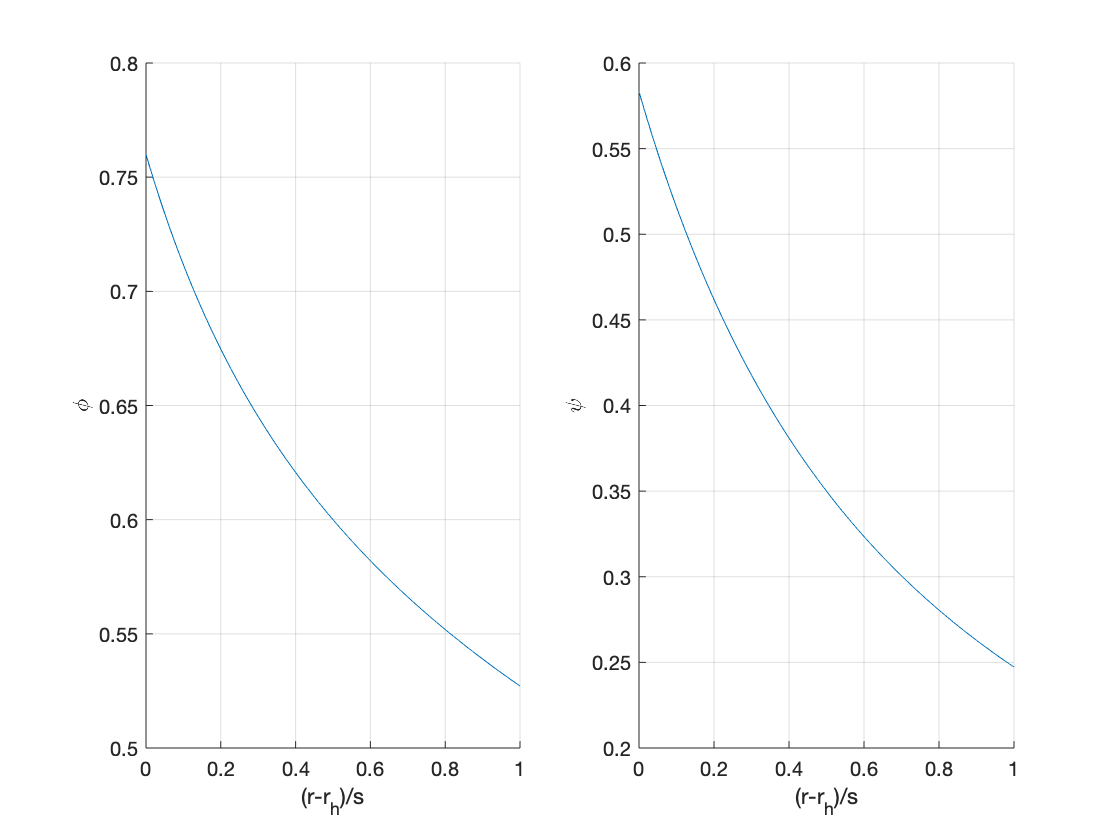

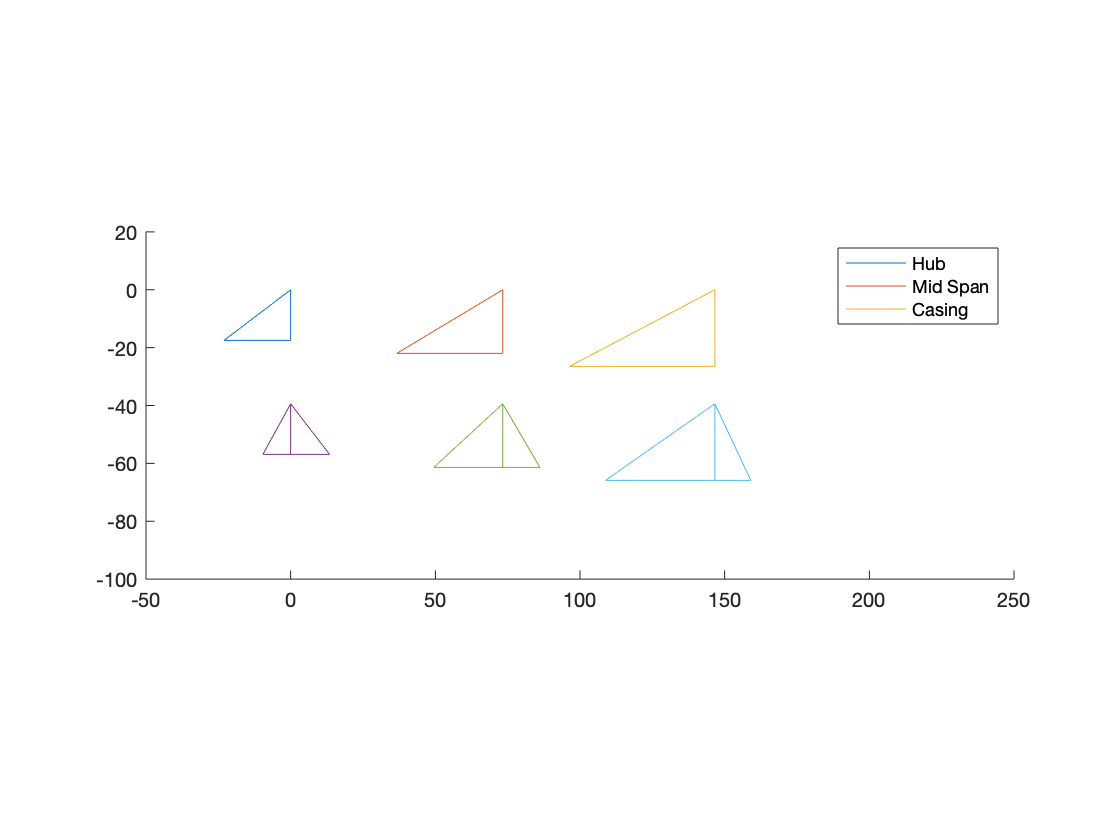

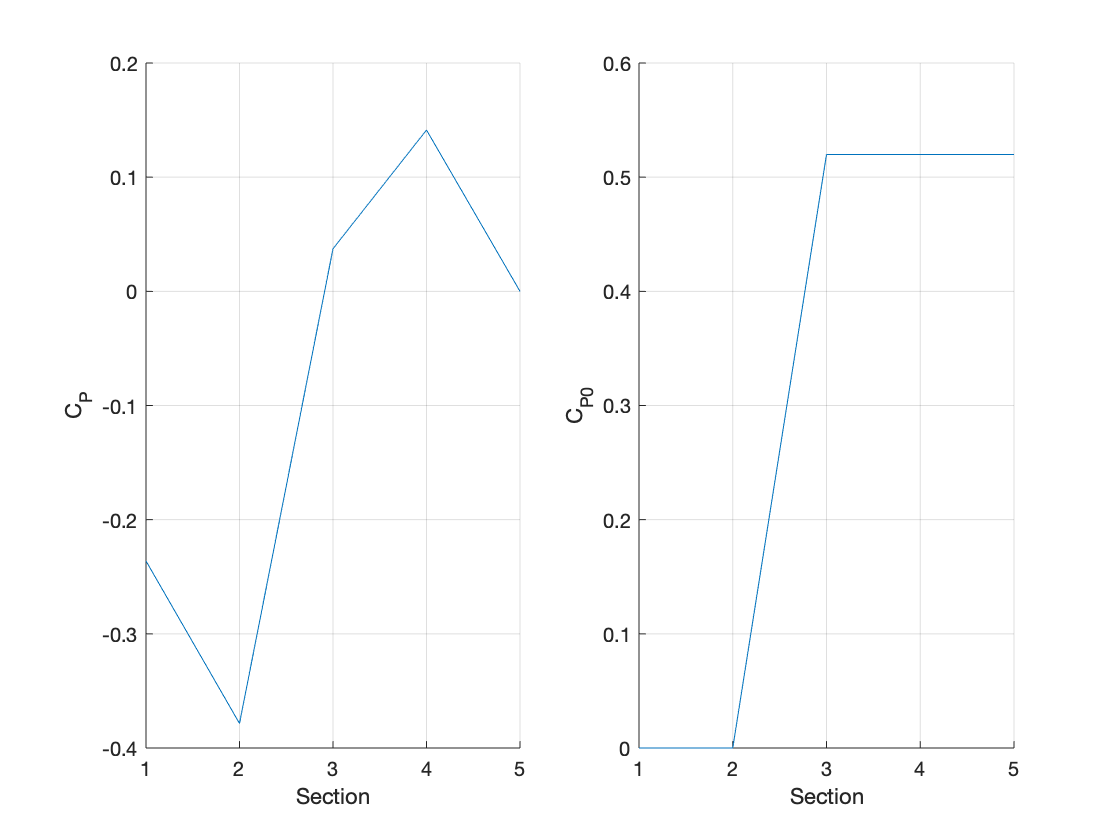

Mean_Line_Design

## Metal Blade Angles

MetalAngles

## Print Blades

yshift =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


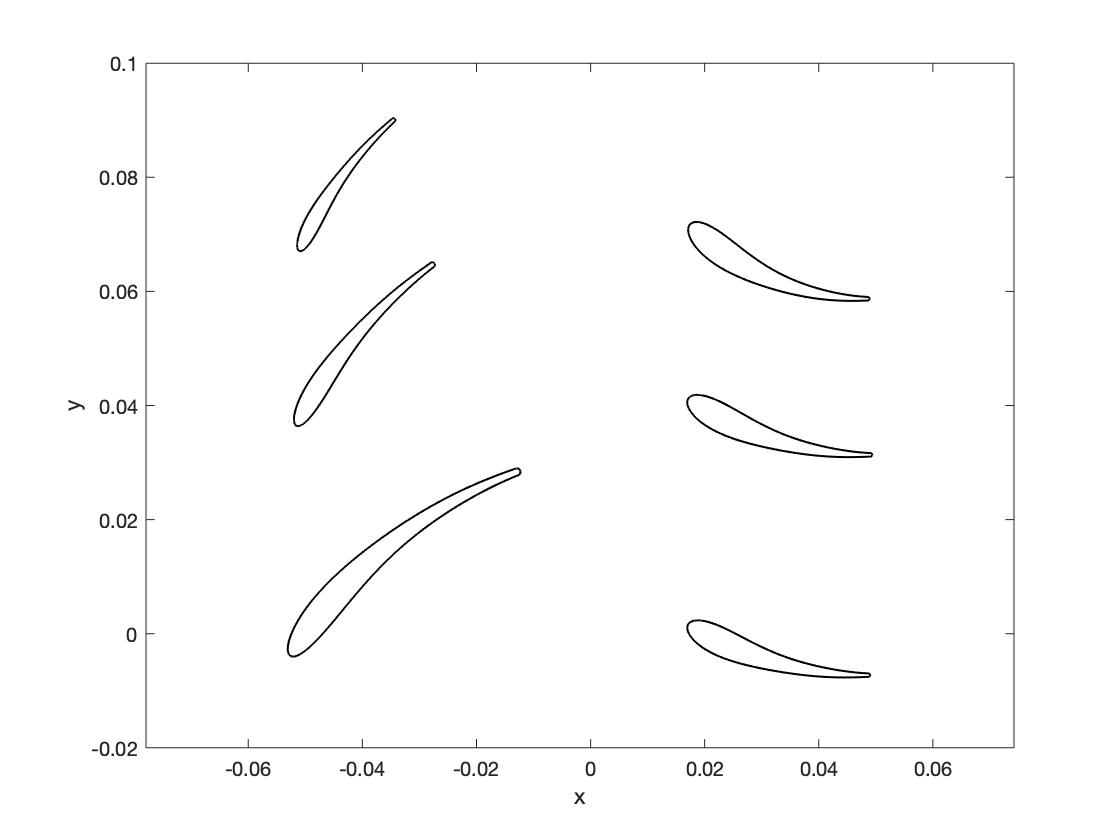

yshift =     0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015


yshift =     0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028


yshift =     0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041


yshift =     0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052


yshift =     0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


yshift =     0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072


yshift =     0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


yshift =     0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088


yshift =     0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


yshift =     0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099


yshift =     0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104


yshift =     0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


yshift =     0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109


yshift =     0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110


yshift =     0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110


yshift =     0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109


yshift =     0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


yshift =     0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104


yshift =     0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099


yshift =     0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


yshift =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


yshift =     0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015


yshift =     0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028


yshift =     0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041


yshift =     0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052


yshift =     0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


yshift =     0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072    0.0072


yshift =     0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


yshift =     0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088


yshift =     0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


yshift =     0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099


yshift =     0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104


yshift =     0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


yshift =     0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109


yshift =     0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110


yshift =     0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110


yshift =     0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109


yshift =     0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


yshift =     0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104    0.0104


yshift =     0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099


yshift =     0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


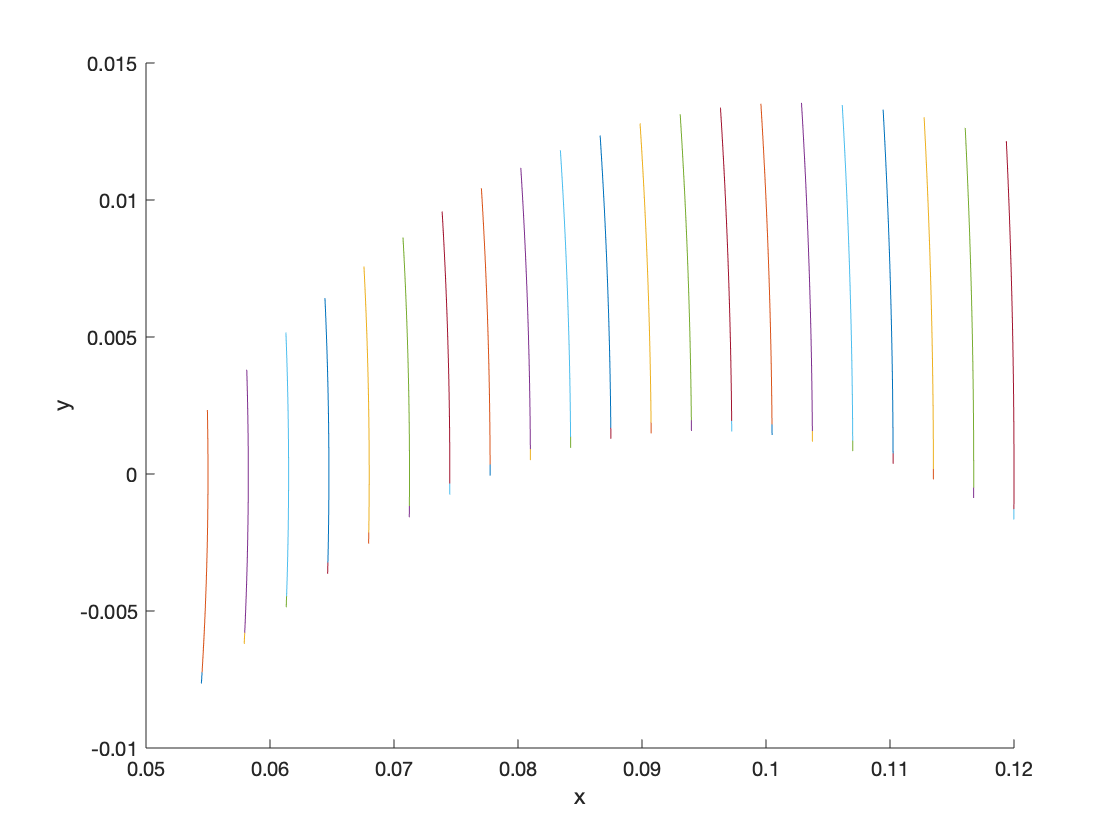

Error using fprintf
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in PrintGeometry (line 70)
fprintf(fid,'Closed Index arclength\n');

PrintGeometry